% lb = [-5 3];
% ub = [1.03 3.1];
% ndec = 2; % so chu so thap phan
% numTotal = (ub'-lb')/10^(-ndec) + 1;
% n = floor(log2(numTotal)) + 1;
% len = sum(n);
% popSize = 50;
% 
% pop = rand(popSize, len);
% pop(pop>0.5) = 1;
% pop(pop<0.5) = 0;
% pop
% cl = [1; cumsum(n(1:end-1)+1)];
% cu = cumsum(n);
% floatNum = zeros(popSize, length(n));
% % vars = cell(length(n),1);
% for i=1:length(n)
%     tmp = pop(:,cl(i):cu(i));
%     tmp2(:,i) = bi2de(tmp,2,'left-msb');
% %     gene encoding, with lb = lower bound, ub = upper bound
% %     X = X_lb + bin2dec(Xbin)*(X_ub-X_lb)/(2^bitlength-1)
%     floatNum(:,i) = lb(i) + bi2de(tmp,2,'left-msb') ...
%         *(ub(i)-lb(i))/(2^(n(i))-1);
% end
% floatNum
% % binNum = zeros(popSize,len);

% cumsum(n(1:end-1))+1

% % clear tmp
% for i=1:length(n)
%     binNum(:,cl(i):cu(i)) = de2bi(round((floatNum(:,i)-lb(i))*(2^(n(i))-1)/(ub(i)-lb(i))),'left-msb');
% end
% all(pop==binNum,'all')

load COMTraj.mat
popSize = 1000;
maxGens = 100;
probCrossover = 1;
probMutation = 0.0077;
useClamping=1; useSigmaScaling=1; useSUS=1; crossoverType=3; useMaskRepositories=1; ... % set additional functions 
flagFreq=0.01;unflagFreq=0.01;flagPeriod=200;... % clamping parameters
sigmaScalingCoeff=1;... % sigma scaling parameters
maskReposFactor=5;... % mask repositories parameters
lb = [-100 -100 -100 -100 1];
ub = [100 100 100 100 20];
COMxmax=300;ndec=2;... % constraints
Len1=50; Len2=400; Len3=400; h1=20;
l1=25; l2=200; l3=200; l4=300;
% exoskeleton parameters
m1=1; m2=5; m3=6; m4=20;
% input parameters
COMRef=[-xCOM+0.172 yCOM-0.06]*1e3;

%% JOINT PROPERTIES
% initial joint angle
ti=[0 -0.2241 -1.3467 1.5708];
% initial joint speed
dti=[0 0 0 0];
% initial joint acceleration
ddti=[0 0 0 0];
% final joint angle
tf=[0 0 0 0];
% final joint speed
dtf=[0 0 0 0];
% joint upper bound constraints
lbJ=[0 7*pi/4 5*pi/4 0 % angle
    -250 -212 -290 -200]; % torque
% joint lower bound constraints
ubJ=[1e-3 2*pi 2*pi pi % angle
    250 212 290 200]; % torque

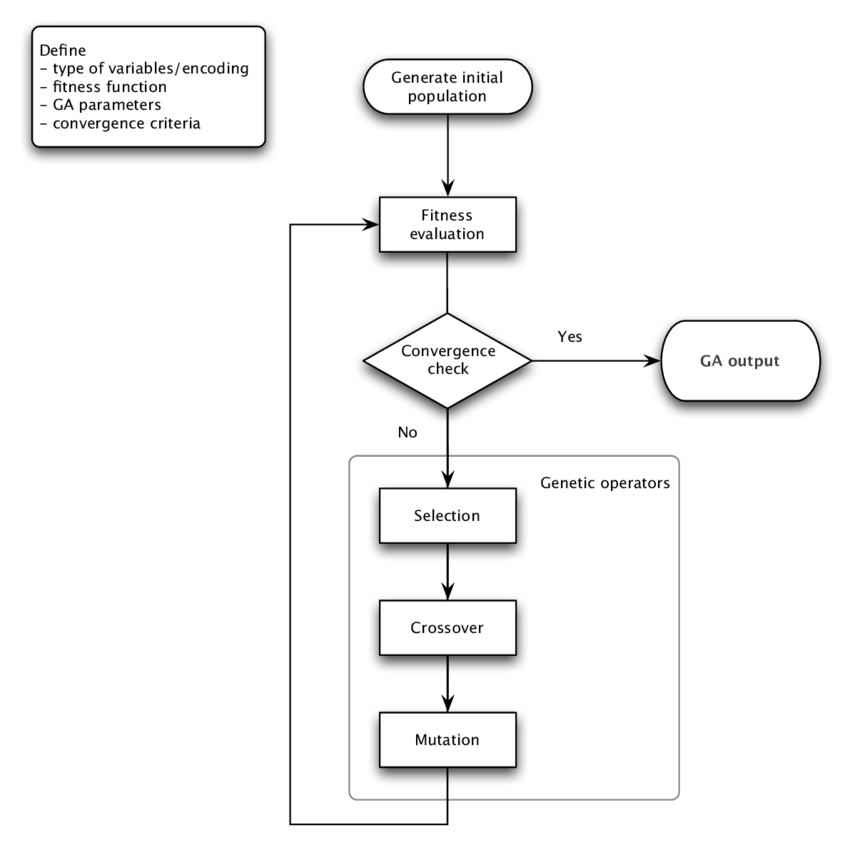

[decPop,binPop,n,numVars,cl,cu,len] = GAInitPop(popSize,lb,ub,ndec);

% generate time variable
nt = size(COMRef,1);
thetas = zeros(nt,length(lb)-1);

fitnessVals = zeros(1,popSize);

% preallocate vectors for recording the average and maximum fitness in each
% generation
avgFitnessHist=zeros(1,maxGens+1);
maxFitnessHist=zeros(1,maxGens+1);
eliteIndiv=[];
eliteFitness=-realmax;

% clamping parameters
if useClamping
    flaggedGens=-ones(1,len);
else
    flaggedGens=0;
end

% crossover masks to use if crossoverType==1.
if crossoverType==1
    mutationOnlycrossmasks=false(popSize,len);
else
    mutationOnlycrossmasks=0;
end

% pre-generate two “repositories” of random binary digits from which the  
% the masks used in mutation and uniform crossover will be picked. 
% maskReposFactor determines the size of these repositories.
if useMaskRepositories
    uniformCrossmaskRepos = rand(popSize/2,(len+1)*maskReposFactor) < 0.5;
    mutmaskRepos = rand(popSize,(len+1)*maskReposFactor) < probMutation;
else
    uniformCrossmaskRepos = 0;
    mutmaskRepos = 0;
end


for gen=0:maxGens
    
    as = decPop(:,1:end-1); % a coefficients
        t_f = decPop(:,end); % final time (s)
                                    
    % FITNESS EVALUATION                   
    fitnessVals = GAFitnessFunc(Len1,Len2,Len3,h1,...
                       l1,l2,l3,l4, ...
                       m1,m2,m3,m4, ...
                       lb,ub,lbJ,ubJ, ... % constraints
                       fitnessVals,COMRef,thetas,as,t_f,nt,popSize,len,...
                       ti,dti,ddti,tf,dtf);
    
    %% RECORD THE BEST CANDIDATE
    [avgFitnessHist, maxFitnessHist, eliteFitness, eliteIndiv] = ...
        GAEliteCandidate(decPop, fitnessVals, gen, ...
            avgFitnessHist, maxFitnessHist, eliteFitness, eliteIndiv);
    
    %% ENCODING
    binPop = GAEncoding(binPop,decPop,n,numVars,lb,ub,cl,cu);
    
    %% SELECTION
    [firstParents,secondParents] = GASelection(binPop, fitnessVals, popSize, ...
    useSigmaScaling, sigmaScalingCoeff, useSUS);
    
    %% CROSSOVER
    binPop = GACrossover(firstParents,secondParents,popSize,len,probCrossover,... standard crossover parameters
            crossoverType,useMaskRepositories,mutationOnlycrossmasks,maskReposFactor,uniformCrossmaskRepos);
    
    %% MUTATION
    binPop = GAMutation(binPop, popSize, len, probMutation, ...
            useMaskRepositories, maskReposFactor, mutmaskRepos, ...
            useClamping, flagFreq, unflagFreq, flagPeriod, flaggedGens);
    
    %% DECODING
    decPop = GADecoding(binPop,decPop,n,numVars,lb,ub,cl,cu);
end

% repmat(lb,popSize,1) < [thetas taus]
% repmat(lb,numVars,1)
eliteIndiv

eliteIndiv =    12.9978   64.2689   98.5839   17.0629    1.1207


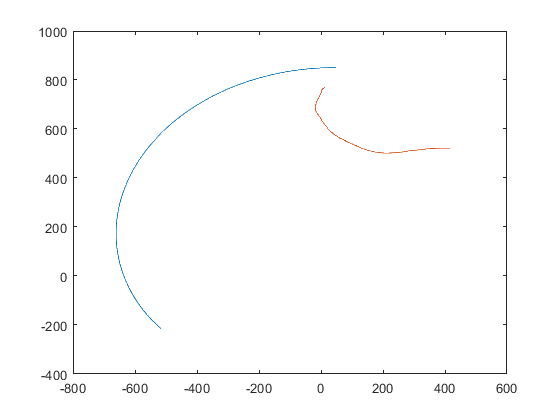

thetas1 = zeros(nt,length(lb)-1);
ts = linspace(lb(end),eliteIndiv(end),nt);
for j=1:4
    thetas1(:,j) = JointTrajFit(ts,eliteIndiv(j),eliteIndiv(end),...
        tf(j),ti(j),dtf(j),dti(j),ddti(j));
end
COM_est = JointCOMTraj(Len1,Len2,Len3,h1,...
                       l1,l2,l3,l4,...
                       m1,m2,m3,m4,...
                       thetas1(:,1), thetas1(:,2), thetas1(:,3), thetas1(:,4));
plot(COM_est(:,1),COM_est(:,2),COMRef(:,1),COMRef(:,2))

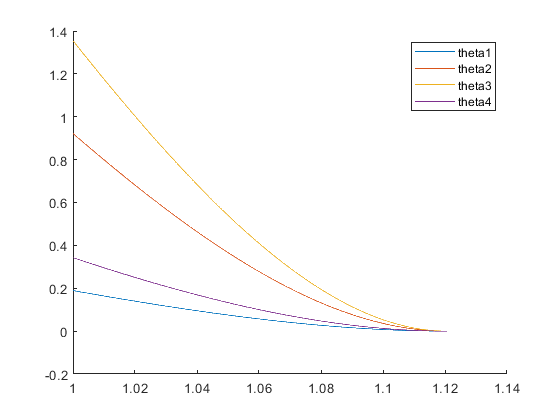

clf, close all
figure(2)
hold on
plot(ts,thetas1)
% plot(ts,thetas1(:,2))
% plot(ts,thetas1(:,3))
% plot(ts,thetas1(:,4))
legend(['theta1'; 'theta2'; 'theta3'; 'theta4'])
hold off